clc;
clear;

% Parámetros de la señal
A = 2; % Amplitud de la señal
des = deg2rad(45); % Desplazamiento de fase
f = 125; % Frecuencia de la señal (Hz)


%##############  Esto es lo que se debe cambiar... #################%
% Parámetros de muestreo
fs = 1000; % Frecuencia de muestreo (Hz)
tiempo = 1000; % Tiempo total de grabación (milisegundos)



% Tiempo continuo y muestreo
T = tiempo / 1000; % Convertir tiempo a segundos
Ts = 1 / fs; % Periodo de muestreo
t = 0:Ts:T-Ts; % Vector de tiempo discreto (muestreo)

% Definir un tiempo continuo 
t_original = 0:1e-6:T; % Usamos una resolución mucho más fina para la señal original

% Señal original en tiempo continuo
x_original = A * sin(2 * pi * f * t_original + des);

% Señal muestreada
x_sampled = A * sin(2 * pi * f * t + des);

% Valores de las muestras
disp('Valores de las muestras:');

Valores de las muestras:


disp(x_sampled);

    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142   -0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000

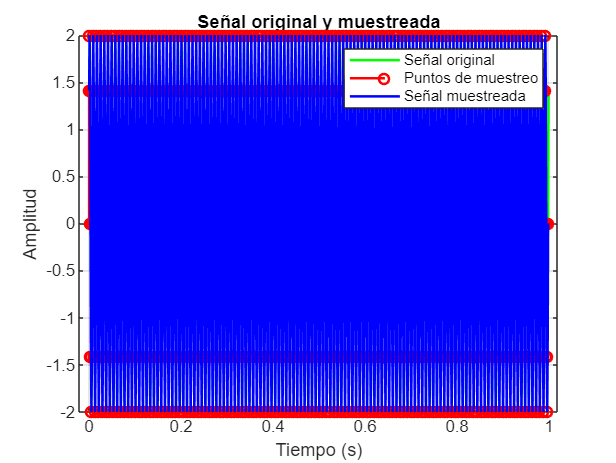


% Graficar
figure;

% Señal original
plot(t_original, x_original, 'g', 'LineWidth', 1.5);
hold on;

% Puntos de muestreo
stem(t, x_sampled, 'r', 'LineWidth', 1.5);

% Señal muestreada
plot(t, x_sampled, 'b', 'LineWidth', 1.5);

% Gráfica
title('Señal original y muestreada');
xlabel('Tiempo (s)');
ylabel('Amplitud');
legend('Señal original', 'Puntos de muestreo', 'Señal muestreada');
grid on;
hold off;